clear;
load('Data\Indian_pines.mat');
him = indian_pines;
clear indian_pines;

[m, n, l] = size(him);
X = reshape(him, [], l);
[Rn, Rs] = noise_signal_estim(him);
Rn_ = pinv(sqrtm(Rn));
[V, D] = eig(Rn_ * Rs * Rn_);
Y = X * V;

him_ = reshape(Y, [m, n, l]);
snr = diag(D);

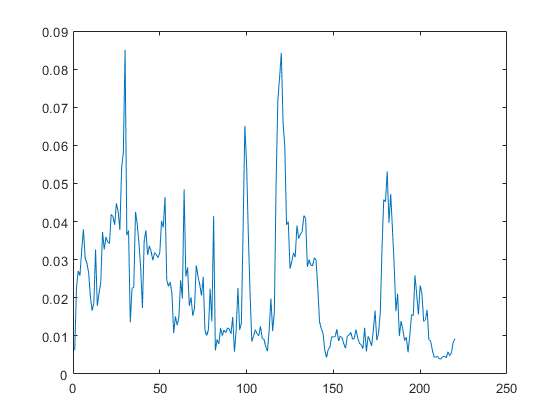

len = sum(V(:, 1:5).^2, 2);
plot(len);

[~, idx] = sort(len, 'descend');

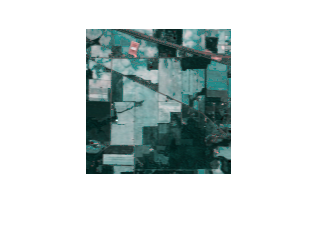

h = HSI(him(:, :, idx(1:3)));
h.preprocess('norm');
imshow(h.him);